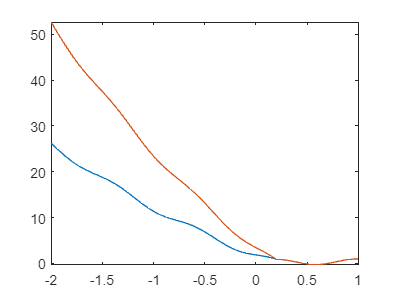

x = 2.1554

clear all;
f_kar_zew = @(x, ogr) max(0, (x-ogr(1)).*(x-ogr(2)) );
f_kar_wew = @(x, ogr) log(abs(1./((x-ogr(1)).*(x-ogr(2)))));

epsilon = 1e-3;
N_max = 1000;
ogr = [0.2, 4];
x0 = -4;
f= @(x) 0.2.*x+0.6.*sin(8.*x)+(0.1.*x.^2-0.5).^2;
c = 2;
c_mod = 2;
x = find_ogr(f, x0, ogr, f_kar_zew, c, c_mod, epsilon, N_max)

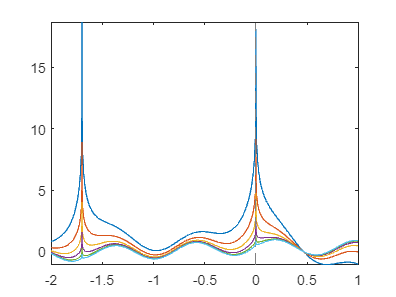

x = -0.9905



ogr = [-1.7, 0];
x0 = -1.3;
c_mod = 0.5;
x = find_ogr(f, x0, ogr, f_kar_wew, c, c_mod, epsilon, N_max)

x = -0.9905


x0 = -1.123;
x = find_ogr(f, x0, ogr, f_kar_wew, c, c_mod, epsilon, N_max)

function [x] = find_ogr(f, x0, ogr, f_kar, c, c_mod, epsilon, Nmax)

    i = 1;
    x_prev = x0;
    figure;
    while(i < Nmax)
    
        f_cel = @(x_p) f(x_p) + c.*f_kar(x_p, ogr);

        fplot(f_cel, [-2, 1])
        hold on;

        x = fminsearch(f_cel, x_prev);

        if(abs(x - x_prev) < epsilon)
            return;
        end %if
        c = c_mod.*c;
        x_prev = x;
        
    end %while

    x = realmax();
end %function